clear
clc

FactorServicio=1.65; %10 horas diarias, carga tipo 3

TCA1iz=readtable("MatLab cinematica\docTXT\ArfadaCaso1iz.txt");
TCA2iz=readtable("MatLab cinematica\docTXT\ArfadaCaso2iz.txt");
TCA3iz=readtable("MatLab cinematica\docTXT\ArfadaCaso3iz.txt");
TCC1iz=readtable("MatLab cinematica\docTXT\CabeceoCaso1iz.txt");
TCC2iz=readtable("MatLab cinematica\docTXT\CabeceoCaso2iz.txt");
TCC3iz=readtable("MatLab cinematica\docTXT\CabeceoCaso3iz.txt");
TCB1iz=readtable("MatLab cinematica\docTXT\BalanceoCaso1iz.txt");
TCB2iz=readtable("MatLab cinematica\docTXT\BalanceoCaso2iz.txt");
TCB3iz=readtable("MatLab cinematica\docTXT\BalanceoCaso3iz.txt");

TCA1de=readtable("MatLab cinematica\docTXT\ArfadaCaso1de.txt");
TCA2de=readtable("MatLab cinematica\docTXT\ArfadaCaso2de.txt");
TCA3de=readtable("MatLab cinematica\docTXT\ArfadaCaso3de.txt");
TCC1de=readtable("MatLab cinematica\docTXT\CabeceoCaso1de.txt");
TCC2de=readtable("MatLab cinematica\docTXT\CabeceoCaso2de.txt");
TCC3de=readtable("MatLab cinematica\docTXT\CabeceoCaso3de.txt");
TCB1de=readtable("MatLab cinematica\docTXT\BalanceoCaso1de.txt");
TCB2de=readtable("MatLab cinematica\docTXT\BalanceoCaso2de.txt");
TCB3de=readtable("MatLab cinematica\docTXT\BalanceoCaso3de.txt");

TTA1iz=readtable("MatLab cinetica\Torques\MIArfadaC1.txt");
TTA2iz=readtable("MatLab cinetica\Torques\MIArfadaC2.txt");
TTA3iz=readtable("MatLab cinetica\Torques\MIArfadaC3.txt");
TTC1iz=readtable("MatLab cinetica\Torques\MICabeceoC1.txt");
TTC2iz=readtable("MatLab cinetica\Torques\MICabeceoC2.txt");
TTC3iz=readtable("MatLab cinetica\Torques\MICabeceoC3.txt");
TTB1iz=readtable("MatLab cinetica\Torques\MIBalanceoC1.txt");
TTB2iz=readtable("MatLab cinetica\Torques\MIBalanceoC2.txt");
TTB3iz=readtable("MatLab cinetica\Torques\MIBalanceoC3.txt");

TTA1de=readtable("MatLab cinetica\Torques\MDArfadaC1.txt");
TTA2de=readtable("MatLab cinetica\Torques\MDArfadaC2.txt");
TTA3de=readtable("MatLab cinetica\Torques\MDArfadaC3.txt");
TTC1de=readtable("MatLab cinetica\Torques\MDCabeceoC1.txt");
TTC2de=readtable("MatLab cinetica\Torques\MDCabeceoC2.txt");
TTC3de=readtable("MatLab cinetica\Torques\MDCabeceoC3.txt");
TTB1de=readtable("MatLab cinetica\Torques\MDBalanceoC1.txt");
TTB2de=readtable("MatLab cinetica\Torques\MDBalanceoC2.txt");
TTB3de=readtable("MatLab cinetica\Torques\MDBalanceoC3.txt");

TorqueA1iz=TTA1iz.Var2/1000;
TorqueA2iz=TTA2iz.Var2/1000;
TorqueA3iz=TTA3iz.Var2/1000;
TorqueC1iz=TTC1iz.Var2/1000;
TorqueC2iz=TTC2iz.Var2/1000;
TorqueC3iz=TTC3iz.Var2/1000;
TorqueB1iz=TTB1iz.Var2/1000;
TorqueB2iz=TTB2iz.Var2/1000;
TorqueB3iz=TTB3iz.Var2/1000;

TorqueA1de=TTA1de.Var2/1000;
TorqueA2de=TTA2de.Var2/1000;
TorqueA3de=TTA3de.Var2/1000;
TorqueC1de=TTC1de.Var2/1000;
TorqueC2de=TTC2de.Var2/1000;
TorqueC3de=TTC3de.Var2/1000;
TorqueB1de=TTB1de.Var2/1000;
TorqueB2de=TTB2de.Var2/1000;
TorqueB3de=TTB3de.Var2/1000;

velocidadA1iz=TCA1iz.VelocidadAngularArfada;
velocidadA2iz=TCA2iz.VelocidadAngularArfada;
velocidadA3iz=TCA3iz.VelocidadAngularArfada;
velocidadC1iz=TCC1iz.VelocidadAngularCabeceo;
velocidadC2iz=TCC2iz.VelocidadAngularCabeceo;
velocidadC3iz=TCC3iz.VelocidadAngularCabeceo;
velocidadB1iz=TCB1iz.VelocidadAngularBalanceo;
velocidadB2iz=TCB2iz.VelocidadAngularBalanceo;
velocidadB3iz=TCB3iz.VelocidadAngularBalanceo;
velocidadA1de=TCA1de.VelocidadAngularArfada;
velocidadA2de=TCA2de.VelocidadAngularArfada;
velocidadA3de=TCA3de.VelocidadAngularArfada;
velocidadC1de=TCC1de.VelocidadAngularCabeceo;
velocidadC2de=TCC2de.VelocidadAngularCabeceo;
velocidadC3de=TCC3de.VelocidadAngularCabeceo;
velocidadB1de=TCB1de.VelocidadAngularBalanceo;
velocidadB2de=TCB2de.VelocidadAngularBalanceo;
velocidadB3de=TCB3de.VelocidadAngularBalanceo;



PotenciaA1iz=abs(TorqueA1iz.*velocidadA1iz)*FactorServicio;
PotenciaA2iz=abs(TorqueA2iz.*velocidadA2iz)*FactorServicio;
PotenciaA3iz=abs(TorqueA3iz.*velocidadA3iz)*FactorServicio;
PotenciaC1iz=abs(TorqueC1iz.*velocidadC1iz)*FactorServicio;
PotenciaC2iz=abs(TorqueC2iz.*velocidadC2iz)*FactorServicio;
PotenciaC3iz=abs(TorqueC3iz.*velocidadC3iz)*FactorServicio;
PotenciaB1iz=abs(TorqueB1iz.*velocidadB1iz)*FactorServicio;
PotenciaB2iz=abs(TorqueB2iz.*velocidadB2iz)*FactorServicio;
PotenciaB3iz=abs(TorqueB3iz.*velocidadB3iz)*FactorServicio;

PotenciaA1de=abs(TorqueA1de.*velocidadA1de)*FactorServicio;
PotenciaA2de=abs(TorqueA2de.*velocidadA2de)*FactorServicio;
PotenciaA3de=abs(TorqueA3de.*velocidadA3de)*FactorServicio;
PotenciaC1de=abs(TorqueC1de.*velocidadC1de)*FactorServicio;
PotenciaC2de=abs(TorqueC2de.*velocidadC2de)*FactorServicio;
PotenciaC3de=abs(TorqueC3de.*velocidadC3de)*FactorServicio;
PotenciaB1de=abs(TorqueB1de.*velocidadB1de)*FactorServicio;
PotenciaB2de=abs(TorqueB2de.*velocidadB2de)*FactorServicio;
PotenciaB3de=abs(TorqueB3de.*velocidadB3de)*FactorServicio;

TablaPotenciaSalida=table(PotenciaA1iz,PotenciaA2iz,PotenciaA3iz,PotenciaC1iz,PotenciaC2iz,PotenciaC3iz,PotenciaB1iz,PotenciaB2iz,PotenciaB3iz,PotenciaA1de,PotenciaA2de,PotenciaA3de,PotenciaC1de,PotenciaC2de,PotenciaC3de,PotenciaB1de,PotenciaB2de,PotenciaB3de);

PRMSPotenciaA1iz=rms(PotenciaA1iz);
PRMSPotenciaA2iz=rms(PotenciaA2iz);
PRMSPotenciaA3iz=rms(PotenciaA3iz);
PRMSPotenciaC1iz=rms(PotenciaC1iz);
PRMSPotenciaC2iz=rms(PotenciaC2iz);
PRMSPotenciaC3iz=rms(PotenciaC3iz);
PRMSPotenciaB1iz=rms(PotenciaB1iz);
PRMSPotenciaB2iz=rms(PotenciaB2iz);
PRMSPotenciaB3iz=rms(PotenciaB3iz);

PRMSPotenciaA1de=rms(PotenciaA1de);
PRMSPotenciaA2de=rms(PotenciaA2de);
PRMSPotenciaA3de=rms(PotenciaA3de);
PRMSPotenciaC1de=rms(PotenciaC1de);
PRMSPotenciaC2de=rms(PotenciaC2de);
PRMSPotenciaC3de=rms(PotenciaC3de);
PRMSPotenciaB1de=rms(PotenciaB1de);
PRMSPotenciaB2de=rms(PotenciaB2de);
PRMSPotenciaB3de=rms(PotenciaB3de);


MatrizPotencia=abs([PotenciaA1iz,PotenciaA2iz,TorqueA3iz,TorqueC1iz,TorqueC2iz,PotenciaC3iz,PotenciaB1iz,PotenciaB2iz,PotenciaB3iz,PotenciaA1de,PotenciaA2de,PotenciaA3de,PotenciaC1de,PotenciaC2de,PotenciaC3de,PotenciaB1de,PotenciaB2de,PotenciaB3de]);

ArregloMaxPotencia=max(MatrizPotencia);
PotenciaMax=max(ArregloMaxPotencia)

PotenciaMax = 2.9140e+03

ArregloPRMS=[PRMSPotenciaA1iz,PRMSPotenciaA2iz,PRMSPotenciaA3iz,PRMSPotenciaC1iz,PRMSPotenciaC2iz,PRMSPotenciaC3iz,PRMSPotenciaB1iz,PRMSPotenciaB2iz,PRMSPotenciaB3iz,PRMSPotenciaA1de,PRMSPotenciaA2de,PRMSPotenciaA3de,PRMSPotenciaC1de,PRMSPotenciaC2de,PRMSPotenciaC3de,PRMSPotenciaB1de,PRMSPotenciaB2de,PRMSPotenciaB3de];
PotenciaRMSMax=max(ArregloPRMS)

PotenciaRMSMax = 1.6738e+03



EficienciaReductor=0.72

EficienciaReductor = 0.7200

EficienciaMotor=0.79

EficienciaMotor = 0.7900


PotenciaMA1iz=PotenciaA1iz/EficienciaReductor/EficienciaMotor;
PotenciaMA2iz=PotenciaA2iz/EficienciaReductor/EficienciaMotor;
PotenciaMA3iz=PotenciaA3iz/EficienciaReductor/EficienciaMotor;
PotenciaMC1iz=PotenciaC1iz/EficienciaReductor/EficienciaMotor;
PotenciaMC2iz=PotenciaC2iz/EficienciaReductor/EficienciaMotor;
PotenciaMC3iz=PotenciaC3iz/EficienciaReductor/EficienciaMotor;
PotenciaMB1iz=PotenciaB1iz/EficienciaReductor/EficienciaMotor;
PotenciaMB2iz=PotenciaB2iz/EficienciaReductor/EficienciaMotor;
PotenciaMB3iz=PotenciaB3iz/EficienciaReductor/EficienciaMotor;

PotenciaMA1de=PotenciaA1de/EficienciaReductor/EficienciaMotor;
PotenciaMA2de=PotenciaA2de/EficienciaReductor/EficienciaMotor;
PotenciaMA3de=PotenciaA3de/EficienciaReductor/EficienciaMotor;
PotenciaMC1de=PotenciaC1de/EficienciaReductor/EficienciaMotor;
PotenciaMC2de=PotenciaC2de/EficienciaReductor/EficienciaMotor;
PotenciaMC3de=PotenciaC3de/EficienciaReductor/EficienciaMotor;
PotenciaMB1de=PotenciaB1de/EficienciaReductor/EficienciaMotor;
PotenciaMB2de=PotenciaB2de/EficienciaReductor/EficienciaMotor;
PotenciaMB3de=PotenciaB3de/EficienciaReductor/EficienciaMotor;

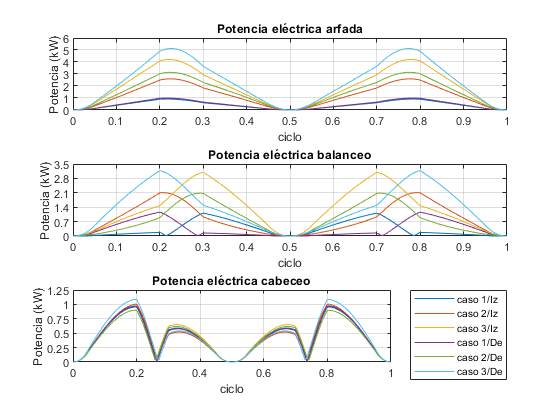



figure()
subplot(3,1,1)
plot(linspace(0,1,160),PotenciaMA1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMA2iz/1000)
plot(linspace(0,1,160),PotenciaMA3iz/1000)
plot(linspace(0,1,160),PotenciaMA1de/1000)
plot(linspace(0,1,160),PotenciaMA2de/1000)
plot(linspace(0,1,160),PotenciaMA3de/1000)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia eléctrica arfada")
yticks(0:6)
ylim([0 6])
ylabel("Potencia (kW)")
xlabel("ciclo")
grid on


subplot(3,1,2)
plot(linspace(0,1,160),PotenciaMB1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMB2iz/1000)
plot(linspace(0,1,160),PotenciaMB3iz/1000)
plot(linspace(0,1,160),PotenciaMB1de/1000)
plot(linspace(0,1,160),PotenciaMB2de/1000)
plot(linspace(0,1,160),PotenciaMB3de/1000)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia eléctrica balanceo")
ylabel("Potencia (kW)")
ylim([0 3.5])
yticks(0:0.7:3.5)
xlabel("ciclo")
grid on


subplot(3,1,3)
plot(linspace(0,1,160),PotenciaMC1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMC2iz/1000)
plot(linspace(0,1,160),PotenciaMC3iz/1000)
plot(linspace(0,1,160),PotenciaMC1de/1000)
plot(linspace(0,1,160),PotenciaMC2de/1000)
plot(linspace(0,1,160),PotenciaMC3de/1000)
hold off

legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia eléctrica cabeceo")
ylabel("Potencia (kW)")
yticks(0:0.25:1.25)
ylim([0 1.25])
xlabel("ciclo")
grid on


PotenciaElectrica=4050/0.79

PotenciaElectrica = 5.1266e+03

VoltajeN=207

VoltajeN = 207

CorrienteMax=PotenciaElectrica/VoltajeN

CorrienteMax = 24.7661

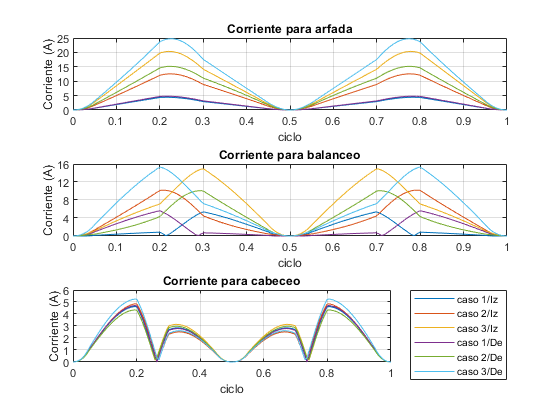




figure()
subplot(3,1,1)
plot(linspace(0,1,160),PotenciaMA1iz/VoltajeN)
hold on
plot(linspace(0,1,160),PotenciaMA2iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMA3iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMA1de/VoltajeN)
plot(linspace(0,1,160),PotenciaMA2de/VoltajeN)
plot(linspace(0,1,160),PotenciaMA3de/VoltajeN)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Corriente para arfada")
yticks(0:5:25)
ylim([0 25])
ylabel("Corriente (A)")
xlabel("ciclo")
grid on


subplot(3,1,2)
plot(linspace(0,1,160),PotenciaMB1iz/VoltajeN)
hold on
plot(linspace(0,1,160),PotenciaMB2iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMB3iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMB1de/VoltajeN)
plot(linspace(0,1,160),PotenciaMB2de/VoltajeN)
plot(linspace(0,1,160),PotenciaMB3de/VoltajeN)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Corriente para balanceo")
ylabel("Corriente (A)")
ylim([0 16])
yticks(0:4:16)
xlabel("ciclo")
grid on


subplot(3,1,3)
plot(linspace(0,1,160),PotenciaMC1iz/VoltajeN)
hold on
plot(linspace(0,1,160),PotenciaMC2iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMC3iz/VoltajeN)
plot(linspace(0,1,160),PotenciaMC1de/VoltajeN)
plot(linspace(0,1,160),PotenciaMC2de/VoltajeN)
plot(linspace(0,1,160),PotenciaMC3de/VoltajeN)
hold off

legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Corriente para cabeceo")
ylabel("Corriente (A)")
yticks(0:6)
ylim([0 6])
xlabel("ciclo")
grid on






In=28

In = 28



Fc=1.25

Fc = 1.2500


In=In*Fc

In = 35